# Homework 1: Double Mass-Spring-Damper system

Matteo Scuderi - 1937090

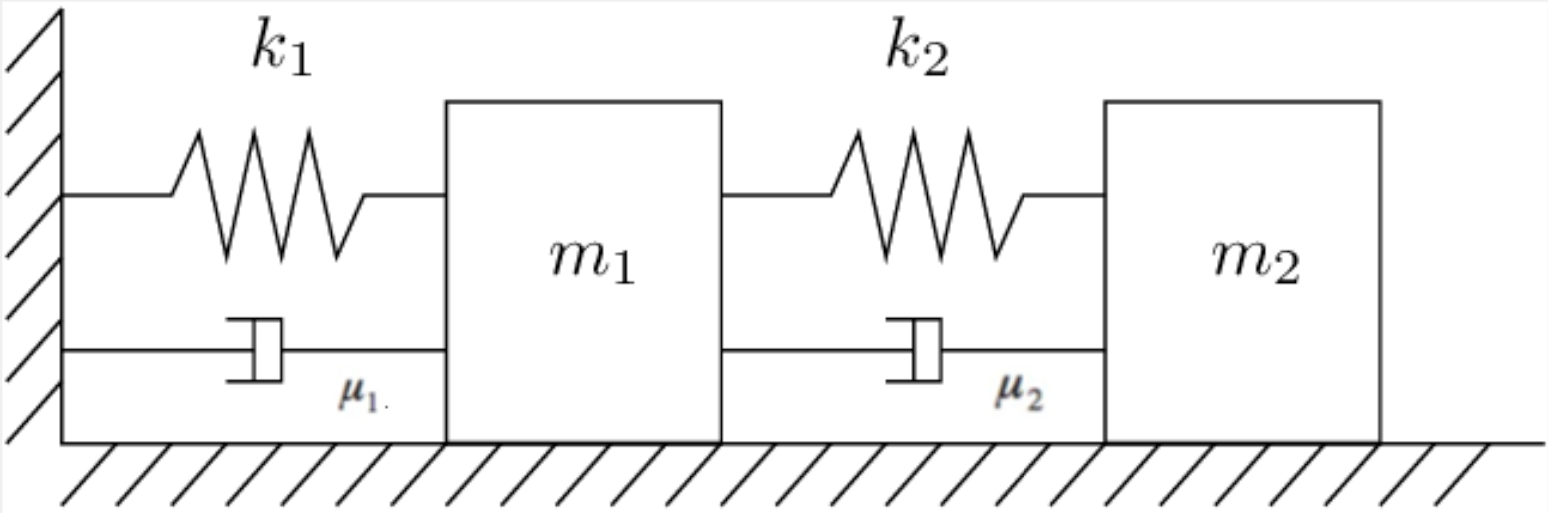

Let's now consider a ***double*** **Mass-Spring-Damper system, **in which we assume to be interested in the position of the first mass $m_1$.

### System Parameters

These are the system's and simulation parameters: 

% ______ Simulation parameters ______ 
% Simulation Time Vector 
t = 0:0.01:10;

% Frequency ranges
om  = logspace(-2,1,300);
om2 = logspace(-2,5,300);
s = tf('s');

% ______ System parameters ______ 
% Underdamped MSD
m1  = 3; % first mass
mu1 = 2; % "low" viscous friction coefficient
k1  = 1; % spring coefficient

% Overdamped MSD
m2  = 3; % second mass
mu2 = 4; % "high" viscous friction coefficient
k2  = 1; % spring coefficient

zeta1 = mu1/(2*sqrt(k1*m1)); % low damping coefficient (m1)
zeta2 = mu2/(2*sqrt(k2*m2)); % high damping coefficient (m2)

disp(strcat(['zeta1 = ', num2str(zeta1), ';  zeta2 = ', num2str(zeta2)]))

zeta1 = 0.57735;  zeta2 = 1.1547


### State Space Representation and Transfer Function

% State space Dynamics' Matrices
A = [0, 1, 0, 0;...
    -(k2+k1)/m1, -(mu2+mu1)/m1, k2/m1, mu2/m1;...
        0, 0, 0, 1;...
    k2/m2, mu2/m2, -k2/m2, -mu2/m2];
B = [0;0;0;1/m2];
C = [1, 0, 0, 0];

% Plant Transfer Funciton
[num, den] = ss2tf(A,B,C,0);
P = tf(num, den)

P =
 
                 0.4444 s + 0.1111
  -----------------------------------------------
  s^4 + 3.333 s^3 + 1.889 s^2 + 0.6667 s + 0.1111
 
Continuous-time transfer function.
Model Properties


#### Bode Magnitude Plot for Double MSD

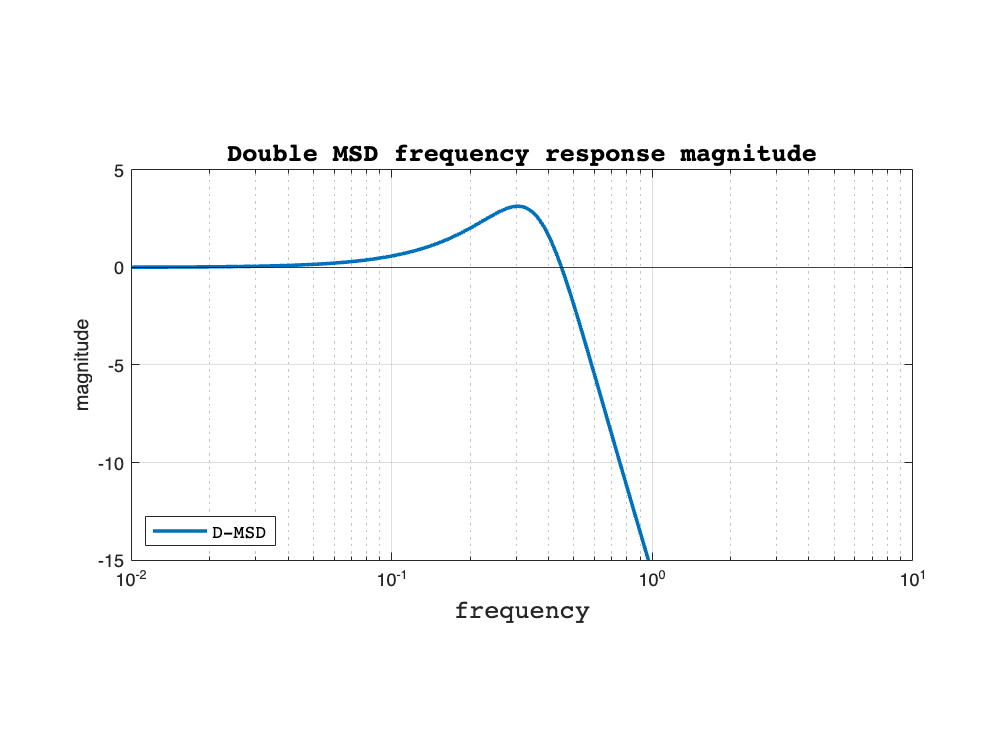

[PMag,~] = bode(P, om);
figure()
semilogx(om, 20*log10(PMag(:)),'LineWidth',2); grid
axis([1E-2,1E1,-15,5])
pbaspect([2,1,1])
yline(0,'k')
ylabel('magnitude')
xlabel('frequency','FontName','courier','FontSize',14)
title('Double MSD frequency response magnitude','FontName','courier','FontSize',14)
legend('D-MSD','FontName','courier','FontSize',10,...
    'Location','southwest','NumColumns',3)

### Open Loop Step Response for double MSD

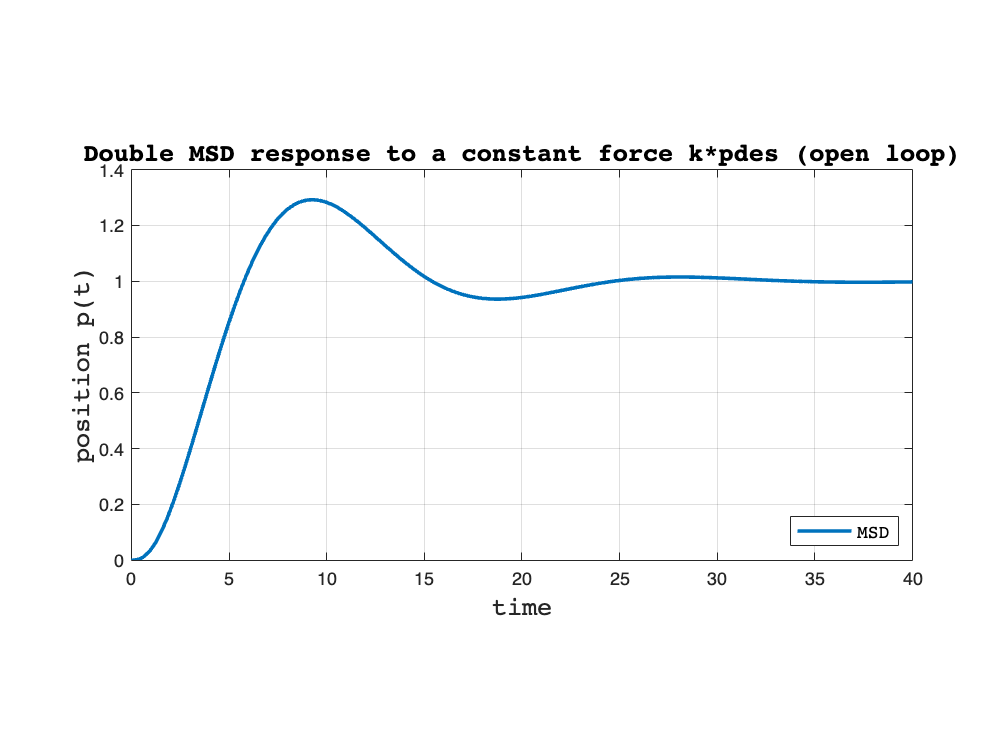

% Step response in open loop
pdes = 1; 
steptime = 40; % set high step time due to low bandwith of the system
StepOpt = stepDataOptions('StepAmplitude',k1*pdes);

[ystep1,time1] = step(P,steptime,StepOpt);

% Plot OL step response
figure()
plot(time1,ystep1,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
ylabel('position p(t)','FontName','courier','FontSize',14)
title('Double MSD response to a constant force k*pdes (open loop)', 'FontName','courier','FontSize',14)
legend('MSD' ,'FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
pbaspect([2,1,1])

## PID vs $H_{\infty }$ Controller Performance

% PID tuning
ops = pidtuneOptions('DesignFocus','reference-tracking');
[C_PID,info] = pidtune(P,'PIDF',ops); 

%PID closed loop
CLoop_PID = loopsens(P,C_PID);  % resulting PID sensitivities 


% Sensitivity Weight Function
Ms = 1.5;
B3s = 1;
As = 0.01;
wS = (s/(Ms)+B3s)/(s+B3s*(As));

%% Constant Control Sensitivity weight function
KSu = 1/50;


[C1,CL1,GAM1] = mixsyn(P,wS,KSu,[]);
GAM1

GAM1 = 1.0992

% H_inf closed Loop
CLoop = loopsens(P,C1);
zpk(C1)

#### Step response with $H_{\infty }$ controller

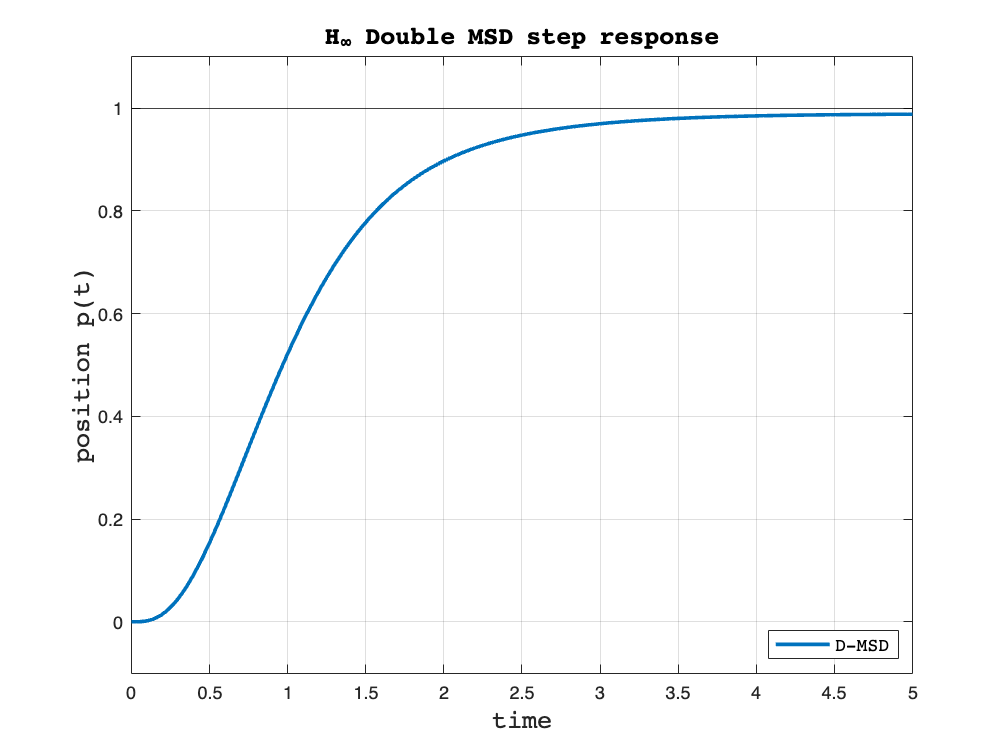

steptime = 5;
[ystep,time1] = step(CLoop.To,steptime);

figure()
plot(time1,ystep,'LineWidth',2); grid
hold on
yline(1,'k-')
xlabel('time','FontName','courier','FontSize',14)
ylabel('position p(t)','FontName','courier','FontSize',14)
title('H_\infty Double MSD step response', 'FontName','courier','FontSize',14)
ylim([-0.1,1.1])
legend('D-MSD' ,'FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)

#### Step control effort with $H_{\infty }$ controller 

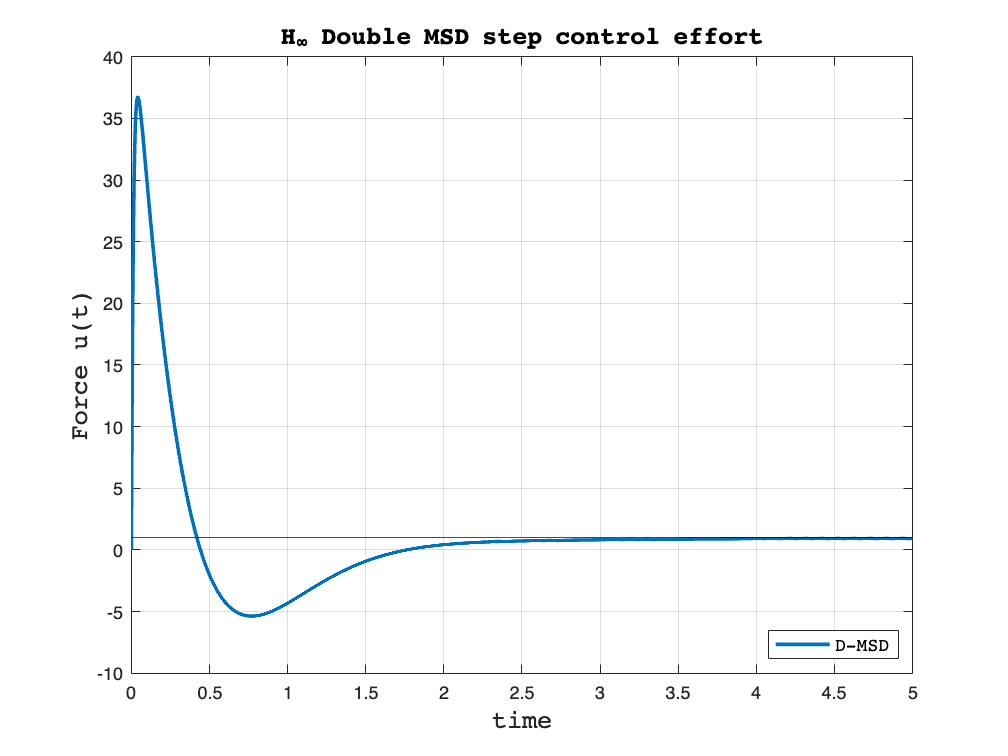

[ustep,time1] = step(CLoop.CSo,steptime);

figure()
plot(time1,ustep,'LineWidth',2); grid
hold on
yline(1,'k-')
xlabel('time','FontName','courier','FontSize',14)
ylabel('Force u(t)','FontName','courier','FontSize',14)
title('H_\infty Double MSD step control effort', 'FontName','courier','FontSize',14)

legend('D-MSD' ,'FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)

#### Step Response with PID controller 

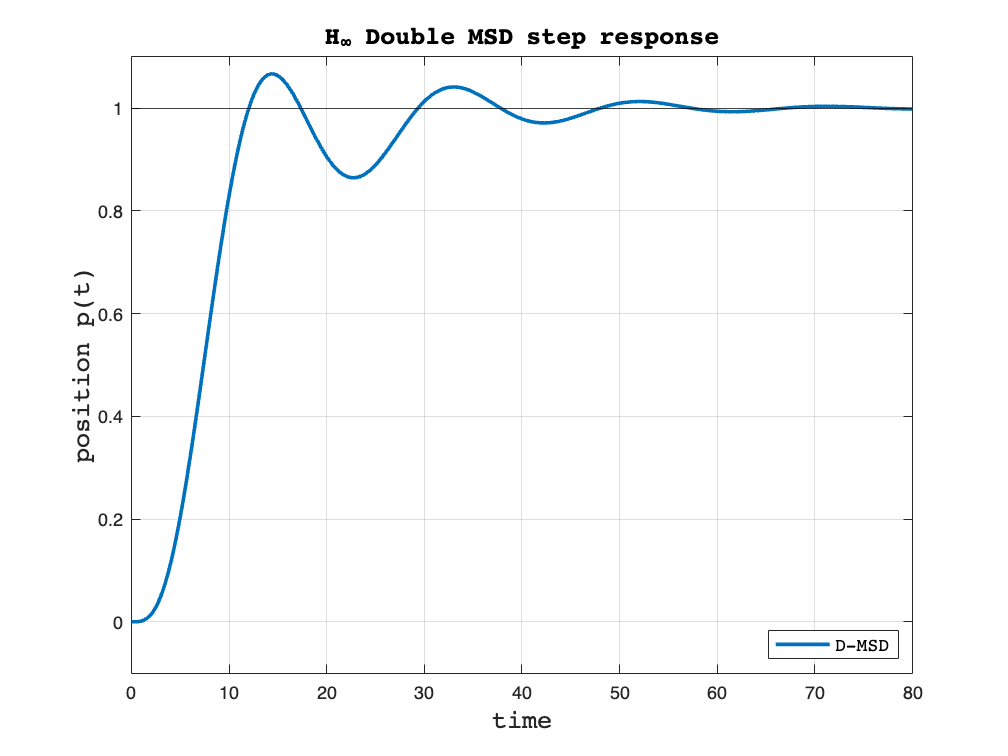

[y_PID,time1] = step(CLoop_PID.To, 80);

figure()
plot(time1,y_PID,'LineWidth',2); grid
hold on
yline(1,'k-')
xlabel('time','FontName','courier','FontSize',14)
ylabel('position p(t)','FontName','courier','FontSize',14)
title('H_\infty Double MSD step response', 'FontName','courier','FontSize',14)
ylim([-0.1,1.1])
legend('D-MSD' ,'FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)

#### Step Control Effort with PID controller 

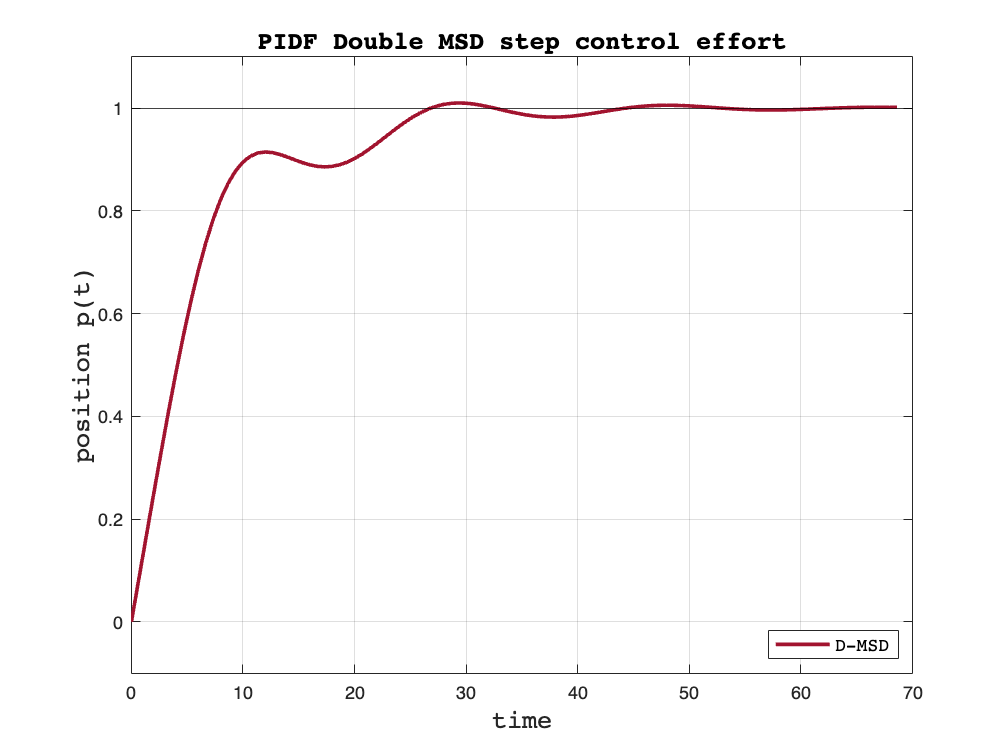

[ustep_PID,time1] = step(CLoop_PID.CSo);

figure()
plot(time1,ustep_PID,'LineWidth',2,'Color',"#A2142F"); grid
hold on
yline(1,'k-')
xlabel('time','FontName','courier','FontSize',14)
ylabel('position p(t)','FontName','courier','FontSize',14)
title('PIDF Double MSD step control effort', 'FontName','courier','FontSize',14)
ylim([-0.1,1.1])
legend('D-MSD' ,'FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)

## Problem 2: DC motor actuation

Let's now consider the same system actuated by a DC motor on the front wheel of the second mass. We're still interested in controlling the position of the first one (unactuated).

### System Parameters

These are the system's and simulation parameters: 

% Motor Parameters from:
% https://www.researchgate.net/publication/272102820_Parameters_Identification_of_a_Permanent_Magnet_DC_Motor/figures?lo=1

% Motor Parameters
Kt = 1.835;
Ke = 1.835;
L = 0.104;
R = 3.05;

% Wheel Radius
r = 0.05;


% State Space Dynamics' Matrices 
A2 = [0, 1, 0, 0, 0;...
    -(k2+k1)/m1, -(mu2+mu1)/m1, k2/m1, mu2/m1, 0;...
        0, 0, 0, 1, 0;...
    k2/m2, mu2/m2, -k2/m2, -mu2/m2, Kt/(m2*r);...
    0, 0, 0, Ke/L, -R/(L*r)];

B2 = [0; 0; 0; 0; 1/(L*r)];

C2 = [1, 0, 0, 0, 0];

% Plant Transfer Funciton
[num2, den2] = ss2tf(A2,B2,C2,0);
P2 = tf(num2, den2)

P2 =
 
                       3137 s + 784.2
  --------------------------------------------------------
  s^5 + 589.9 s^4 + 1741 s^3 + 676.9 s^2 + 247.2 s + 65.17
 
Continuous-time transfer function.
Model Properties


#### Bode Magnitude Plot

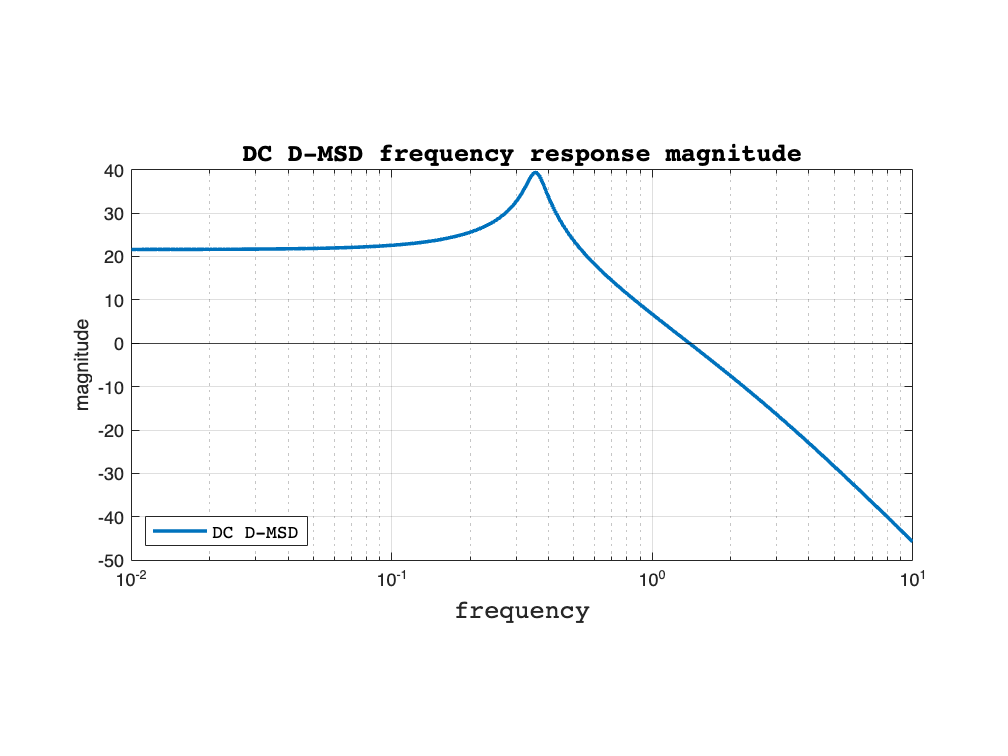

% Bode Magnitude Plot for Plant
[P2Mag,~] = bode(P2, om);
figure()
BodeMSD = semilogx(om, 20*log10(P2Mag(:)),'LineWidth',2); grid
%axis([1E-2,1E1,-15,5])
pbaspect([2,1,1])
yline(0,'k')
ylabel('magnitude')
xlabel('frequency','FontName','courier','FontSize',14)
title('DC D-MSD frequency response magnitude','FontName','courier','FontSize',14)
legend('DC D-MSD','FontName','courier','FontSize',10,...
    'Location','southwest','NumColumns',3)

### Open Loop Step response 

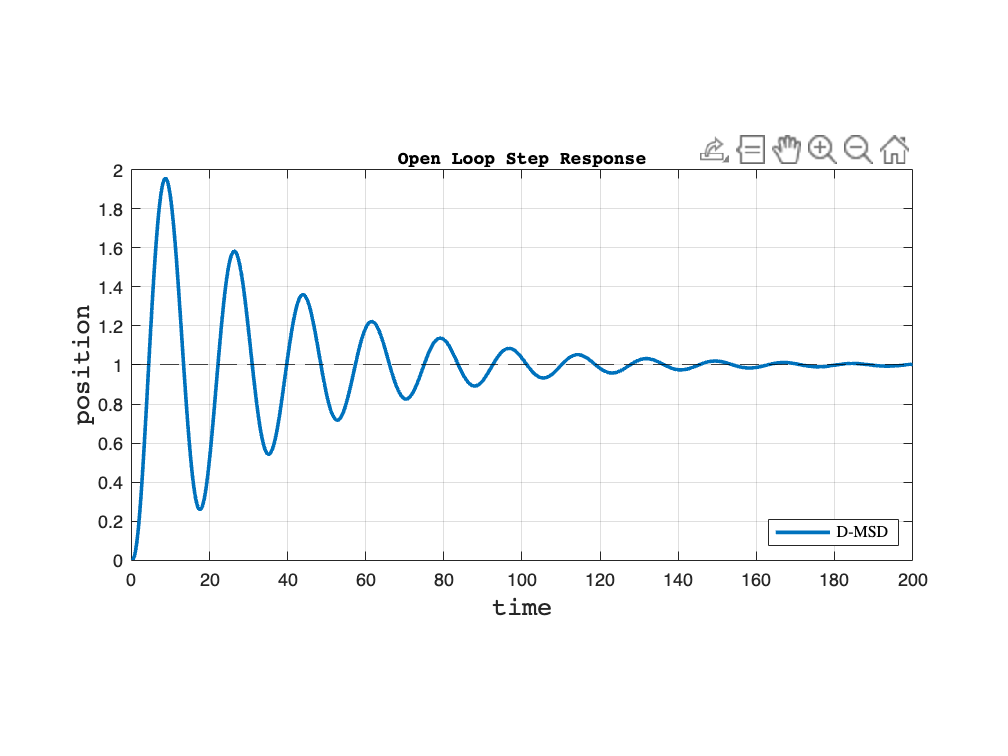

% Step Simulation to reach position pdes = 1
StepOpt = stepDataOptions('StepAmplitude', pdes/dcgain(P2));
steptime = 200; % very slow dynamics
[yOL,timeOL] = step(P2, steptime,StepOpt); %motor OL output

% Step plot
figure()
plot(timeOL,yOL,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
ylabel('position', 'FontName','courier','FontSize',14)
title('Open Loop Step Response', 'FontName','courier','FontSize',10)
yline(pdes,'--k');
legend('D-MSD','Interpreter','latex','Location','southeast')
pbaspect([2,1,1])

### $H_{\infty }$ controller design

This time, prioritize oscillation reduction

%% Sensitivity weight
Ms1 = 1.01;
B3s1 = 1;
As1 = 0.01;

wS2 = (s/(Ms1)+B3s1)/(s+B3s1*(As1));

%% Control Sensitivity weight
Msu1 = 50;
B3su1 = 20;
Asu1 = 0.1;
wSu2 = ((s+(B3su1/Msu1))/(Asu1*s+B3su1));

[C2,CL2,GAM2] = mixsyn(P2,wS2,wSu2,[]);
GAM2

GAM2 = 1.3963

SF2 = loopsens(P2,C2);
zpk(C2)

### Step Response

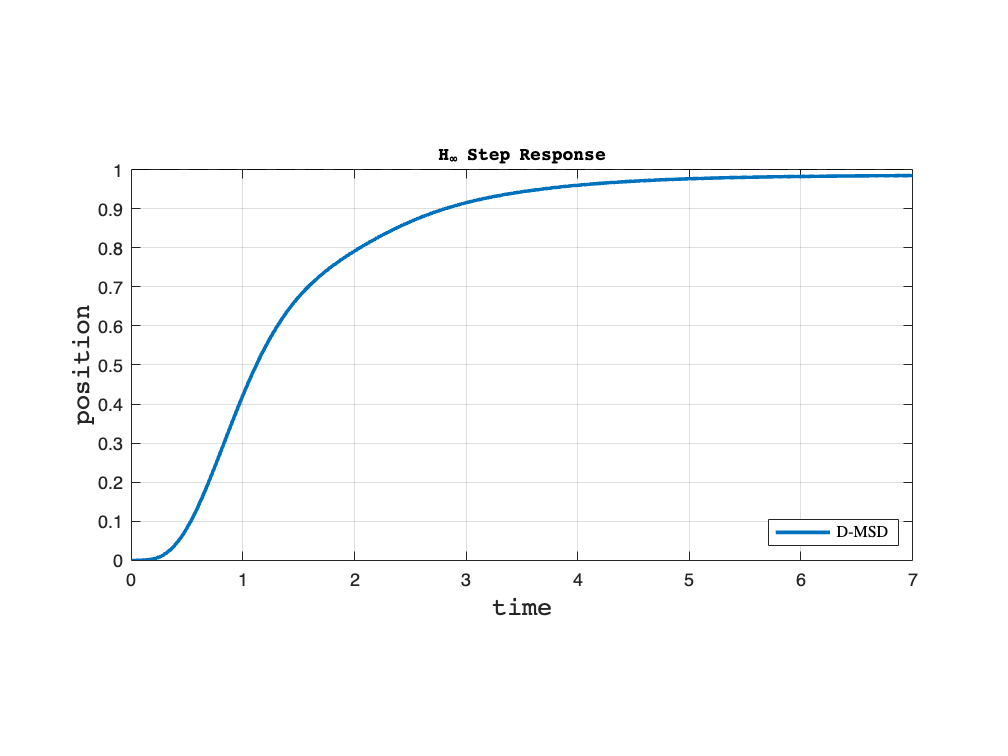

[y2,t2] = step(SF2.To, [0:0.01:7]);
figure()
plot(t2,y2,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
ylabel('position', 'FontName','courier','FontSize',14)
title('H_\infty Step Response', 'FontName','courier','FontSize',10)
yline(pdes,'--k');
legend('D-MSD','Interpreter','latex','Location','southeast')
pbaspect([2,1,1])

### Control Effort

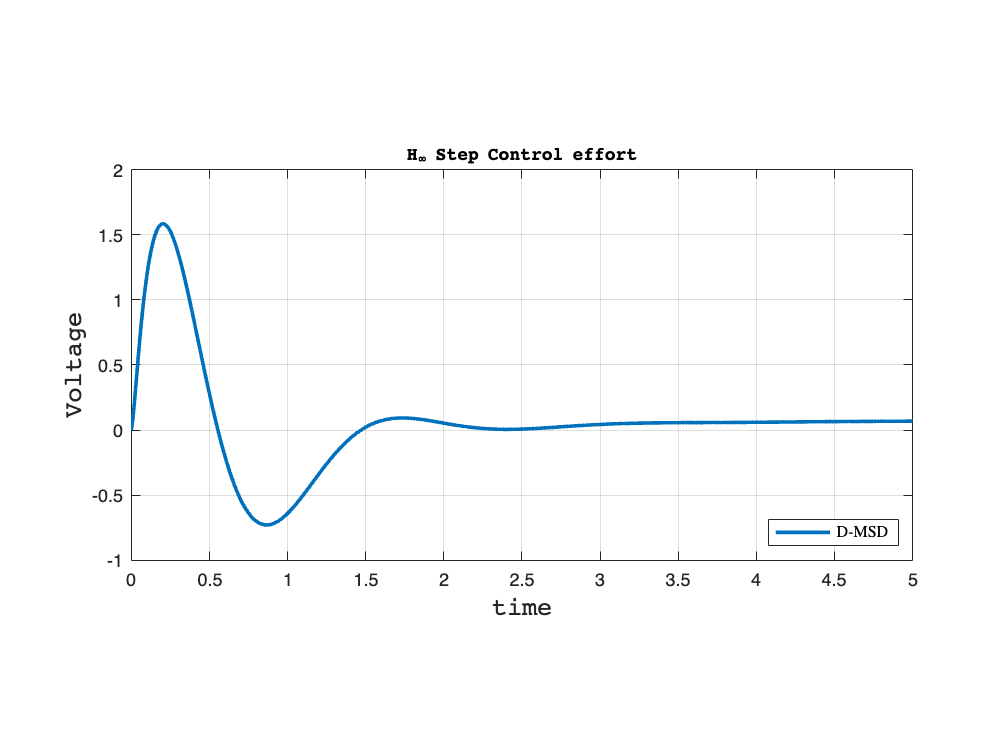

[u2,t2] = step(SF2.CSo, [0:0.01:5]);
figure()
plot(t2,u2,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
ylabel('Voltage', 'FontName','courier','FontSize',14)
title('H_\infty Step Control effort', 'FontName','courier','FontSize',10)
legend('D-MSD','Interpreter','latex','Location','southeast')
pbaspect([2,1,1])